# P3. Diseño de controlador ACC

Sistemas de Control de Vehículos

Grado en Ingeniería Electrónica, Robótica y Mecátronica

Universidad de Málaga

Creado por: David Rodríguez Martínez

Última actualización: 14 Octubre 2026

### Introducción y objetivos

Este archivo contiene a su vez el guión de la práctica y los bloques de código a completar. En esta práctica reutilizaremos el modelo del monoplaza definido anteriormente y **ampliaremos el controlador longitudinal desarrollado en la P1 para su uso como control de crucero adaptativo **o ACC (*adaptive cruise control*). 

En la P1 definimos un controlador longitudinal simple `controlLongitudinal(v_ref, vx, e_int,..). `Hoy nuestro controlador lo definiremos con la forma final necesaria para simular la competición FS Driverless. 

% [Fx, mem] = controlLongitudinal(est, ref, p, mem)

- `est`  = el estado estimado del vehículo (posición, velocidad...)

- `ref` = las referencias de lo que buscamos; en este caso la velocidad de crucero deseada (`ref.v_set`) y la información del coche líder (`ref.lead_X`, `ref.lead_vx`)

- p = párametros (masas, resistencias, límites, ganancias, dt, etc.)

- mem = la memoría del controlador; estado interno que sobrevive de un paso al siguiente (integradores, comandos previos, etc).

🧱 *Sobre el uso de memoria: La mayoría de las ECUs se ejecutan en tiempo discreto donde cada algoritmo limitador, integrador o filtro guarda el estado previo entre ciclos de ejecución. *

Al terminar esta práctica deberás ser capaz de:

- Enteder la diferencia entre el control de crucero clásico y el ACC. 

- Implementar una ley ACC con política de intervalo de tiempo constante (*constant headway, CTH*)  y capacidad de conmutar entre modo velocidad y modo distancia.

- Cerrar el bucle de control longitudinal. 

#### Qué vas a implementar

A) La ley ACC como parte de `controlLongitudinal. `

### Parametros del vehículo, controlador y de la calzada

p = struct(); 

p.m    = 230;      % masa [kg]                              
p.g    = 9.81;     % gravedad [m/s^2]
p.rho  = 1.225;    % densidad del aire [kg/m^3]
p.Cd   = 1.0;      % coef. aerodinámico                       
p.Af   = 1.1;      % área frontal [m^2]                        
p.fr  = 0.022;    % coef. de resistencia a la rodadura       
p.Fx_drive_max = 2500;   % fuerza motriz máxima [N]           
p.Fx_brake_max = 5000;   % fuerza de frenado máxima [N]       
p.theta        = 0;      % inclinación de la calzada [rad]

% adherencia por eje
p.mu_t = 1.5; 
p.mu_d = 0.95*p.mu_t; 

% dinámica lateral del vehículo
p.ld = 0.765; % CG-eje delantero [m] 
p.lt = 0.765; % CG-eje trasero [m]
p.Iz = 130; % inercia en guiñada [kg·m^2]
p.Cad = 35000; % rigidez de deriva delantera [N/rad]
p.Cat = 50000; % rigidez de deriva trasera [N/rad]

% Ley ACC
p.d0 = 6; % distancia mín de parada [m]
p.h = 1.5; % umbral tiempo ("headway") [s]
p.Kv = 1.5; % ganancia en modo velocidad
p.Kg = 0.4; % ganancia modo distancia
p.Kd = 1.0; % ganancia derivativa sobre velocidad relativa
p.jerk_max = 30; % tasa de variación de la aceleración (sobreaceleración; min sacudidas max confort) [m/s^3]

% propios de la simulación 
p.v_set = 25; % velocidad de crucero deseada [m/s] (90 km/h)
p.dt = 0.002; % paso de la simulación
esc.lead_X0 = 30; % posición inicial del líder [m]
esc.Tmax = 22; % tiempo máx simulación 

### Modelo del vehículo

Dado el **estado actual del vehículo, fuerza tractiva aplicada, y el ángulo de giro del volante** deberemos calcular dónde se encuentra el vehículo en el siguiente paso temporal:

function z_next = pasoDinamico(z, u, p, dt)
    Fx = u(1);
    delta = u(2);
    X = z(1); Y =z(2); psi = z(3);
    vx = z(4); vy = z(5); r = z(6);
    L = p.ld + p.lt;
    vx_c = max(vx, 1.0); % velocidad corregida para no dividir por 0 (angulos de deriva)
    
    % ángulos de deriva y fuerzas laterales
    alpha_d = delta - (vy + p.ld*r)/vx_c;
    alpha_t = - (vy - p.lt*r)/vx_c;
    Fyd = p.Cad*alpha_d; % modelo del neumático lineal 
    Fyt = p.Cat*alpha_t; % modelo del neumático lineal

    % Límite de adherencia (presupuesto mu·Fz por eje)
    Fzd = p.m*p.g*p.lt/L;  
    Fzt = p.m*p.g*p.ld/L;

ACC — separación mínima: 19.3 m  (líder frena en t=14 s)


    % Saturación eje delantero 
    Fyd = max(min(Fyd, p.mu_d*Fzd), -p.mu_d*Fzd); 
    % Saturación eje trasero  
    Fyt = max(min(Fyt, p.mu_t*Fzt), -p.mu_t*Fzt);
    % Agarre longitudinal

  sin colisión: separación siempre > 0


    Fx_max = p.mu_d*Fzd + p.mu_t*Fzt;
    Fx = max(min(Fx, Fx_max), - Fx_max);

  velocidad final ego: 30.3 km/h | líder: 28.8 km/h


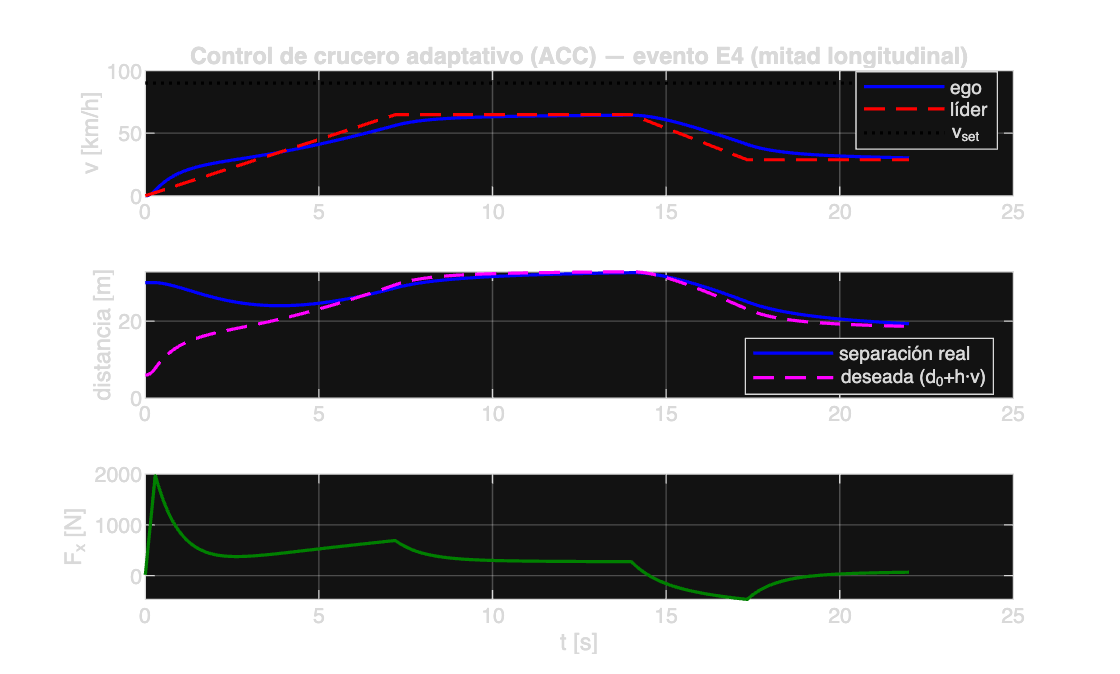


    % Dinámica longitudinal 
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2;      % resitencia aerodinámica
    Rr  = p.fr*p.m*p.g*cos(p.theta);    % rodadura (opuesta al avance)
    Rg = p.m*p.g*sin(p.theta);          % gravedad 

    % Ecuaciones del movimiento (chasis, CG)
    ax_l    = (Fx - Ra - sign(vx)*Rr- Rg) / p.m; % ecuación del movimiento longitudinal (P1)
    ax = ax_l + vy*r; % P1 + acoplamiento (componente centripeta, cambio en la dirección del vector velocidad por el giro)
    ay = (Fyd + Fyt)/p.m - vx*r; 
    dr  = (p.ld*Fyd - p.lt*Fyt)/p.Iz;


    % Integración y cinemática global
    vx_next  = max(vx + ax*dt, 0);
    vy_next  = vy + ay*dt;
    r_next   = r  + dr*dt;
    X_next   = X + (vx*cos(psi) - vy*sin(psi))*dt;
    Y_next   = Y + (vx*sin(psi) + vy*cos(psi))*dt;
    psi_next = psi + r*dt;
    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next];
end

### Controlador velocidad 

Vamos a definir un controlador de velocidad ACC por tiempo constante, ya en su forma final. 

% ACC con intervalo de tiempo constante
function [Fx, mem] = controlLongitudinal(est, ref, p, mem)
    vx = est.vx; 

    %% ley ACC --> CONTROL DE ALTO NIVEL
    d_des = p.d0 + p.h*vx; % distancia deseada
    e_gap = (ref.lead_X - est.X) - d_des; % error del gap/espacio entre vehículos
    
    % MODO VELOCIDAD
    a_vel = p.Kv*(ref.v_set - vx); % controlador proporcional sencillo

    % MODO DISTANCIA
    a_gap = p.Kg*e_gap + p.Kd*(ref.lead_vx - vx); % controlador PD

    % CONMUTADOR
    a_des = min(a_vel, a_gap); % me quedo con la más conservadora

    %% CONTROL A BAJO NIVEL --> de la aceleración a la fuerza
    % vamos a incluir prealimentación (control anticipativo; "feedforward control")
    Fx = p.m*a_des + 0.5*p.rho*p.Cd*p.Af*vx^2 + sign(vx)*p.fr*p.m*p.g; 

    %% SATURACIÓN
    Fx = min(max(Fx, -p.Fx_brake_max), p.Fx_drive_max); 

    %% JERK/TASA DE VARIACIÓN DE LA ACELERACIÓN
    dFx = p.jerk_max*p.m*p.dt; 

    Fx = mem.Fx_prev + max(min(Fx - mem.Fx_prev, dFx), -dFx);
    mem.Fx_prev = Fx;

end

### Geometría del circuito de pruebas

Vamos a simular la prueba del seguimiento de un vehículo lider parte del evento 4 de nuestra competición. En la práctica 5 completaremos el resto de este evento con la frenada de emergencia. 

function hist = simularE4(z0, p, esc, dt)
    % El ego se modela como bicicleta (P2) con delta = 0 + coche líder guionizado. 
    N = round(esc.Tmax/dt);  z = z0;
    Xl = esc.lead_X0; % posición del líder
    mem.Fx_prev = 0; % memoria del controlador
    hist.t=zeros(1,N); hist.vx=zeros(1,N); hist.vl=zeros(1,N);
    hist.Xe=zeros(1,N); hist.Xl=zeros(1,N); hist.gap=zeros(1,N);
    hist.d_des=zeros(1,N); hist.Fx=zeros(1,N);
    for k = 1:N
        t = (k-1)*dt;
        Vl = liderVel(t);  % velocidad del líder 
        Xl = Xl + Vl*dt;   % integra su posición

        % OJO! esto es una simplificación: el estado estimado es la realidad
        est.X = z(1);  est.vx = z(4);

        ref.v_set = p.v_set;  ref.lead_X = Xl;  ref.lead_vx = Vl;

        [Fx, mem] = controlLongitudinal(est, ref, p, mem);

        z = pasoDinamico(z, [Fx;0], p, dt);   % delta = 0: recta

        hist.t(k)=t; hist.vx(k)=z(4); hist.vl(k)=Vl;
        hist.Xe(k)=z(1); hist.Xl(k)=Xl; hist.gap(k)=Xl - z(1);
        hist.d_des(k)=p.d0 + p.h*z(4); hist.Fx(k)=Fx;
    end
end

function Vl = liderVel(t)
% Perfil de velocidad del líder: acelera, crucero, frena.
    v_cru = 18; % 65 km/s
    if t < 8
        Vl = min(v_cru, 2.5*t);            % acelera
    elseif t < 14
        Vl = v_cru;                        % crucero
    else
        Vl = max(8, v_cru - 3*(t-14));     % frena a 8 m/s (30 km/s)
    end
end

### Simulación

dt = p.dt;
z0 = [0; 0; 0; 0; 0; 0]; % estado inicial
% u: variable de control [Fx; delta]
% z: vector de estado del vehículo [X; Y; psi; vx; vy; r]
% X, Y = posicion del CG global
% psi = rumbo, ángulo de guiñada
% vx, vy = velocidades en eje del chasis
% r = velocidad de guiñada

hist = simularE4(z0, p, esc, dt); 

### Resultados 

Deberíamos observar como nuestro vehículo (*ego*) acelera y, en lugar de alcanzar la velocidad requerida de 25, se estabiliza a la velocidad del lider (~18 m/s) manteniendo la distancia deseada. La separación real sigue de cerca a la deseada. Cuando el lider frena (~14s), la separación se reduce pero nuestro vehículo frena a tiempo sin colisión, manteniendo siempre una separación positiva. También se podrá comprobar como la fuerza de tracción cambia de forma suave debido al límite impuesto en la sobreaceleración (*jerk*). 

% Cálculo de las métricas de seguridad
gap_min = min(hist.gap);

fprintf('ACC — separación mínima: %.1f m  (líder frena en t=14 s)\n', gap_min);
if gap_min <= 0
    fprintf('  ¡COLISIÓN! (la ley ACC no mantiene la distancia)\n');
else
    fprintf('  sin colisión: separación siempre > 0\n');
end
fprintf('  velocidad final ego: %.1f km/h | líder: %.1f km/h\n', ...
        hist.vx(end)*3.6, hist.vl(end)*3.6);
% gráficas
figure('Name','L3 · ACC','Color','w');
subplot(3,1,1);
  plot(hist.t, hist.vx*3.6,'b', hist.t, hist.vl*3.6,'r--', hist.t, p.v_set*3.6*ones(size(hist.t)),'k:','LineWidth',1.2);
  ylabel('v [km/h]'); grid on; legend('ego','líder','v_{set}','Location','best');
  title('Control de crucero adaptativo (ACC) — evento E4 (mitad longitudinal)');
subplot(3,1,2);
  plot(hist.t, hist.gap,'b', hist.t, hist.d_des,'m--','LineWidth',1.2);
  ylabel('distancia [m]'); grid on; legend('separación real','deseada (d_0+h·v)','Location','best');
subplot(3,1,3);
  plot(hist.t, hist.Fx,'Color',[0 .5 0],'LineWidth',1.2);
  ylabel('F_x [N]'); xlabel('t [s]'); grid on;

⚡ **Curiosidad**: La aceleración máxima alcanzada por el vehículo son **~8.4 **$\text{m/s}^2$ porque no existe ningún límite explicito a la aceleración en nuestro controlador mas alla del límite de adherencia impuesto por la calzada. Un ACC real impone por la ISO15622 un límite a la aceleración del orden de 2 $\text{m/s}^2$, un límite a la deceleración automática de 3.5 $\text{m/s}^2$, y una sobreaceleración máxima de 2.5 $\text{m/s}^3$. En nuestro caso para un vehículo de competición, ignoramos todos estos límites. 

**🧠 Confort vs Seguridad: **Un limitador de tasa de variación introduce retardo en el bucle de control**.** Cuando se requiere una frenada más intensa, un límite estricto sobre la tasa de variación de la aceleración (*jerk*) retrasa la respuesta del sistema. Por este motivo, los vehículos reales combinan el control de crucero adaptativo (ACC), con limitaciones orientadas al confort, con una **vía de emergencia independiente** que permite eludir dichas limitaciones. En la P5, implementaremos este comportamiento con la función `combinar` que sobrescribe la fuerza longitudinal `Fx` con la frenada máxima *después* de la etapa de control. De este modo, la **frenada automática de emergencia (AEB)** elude el limitador de la tasa de variación de la aceleración.

En nuestro caso, con un límite de jerk tan alto (30 $\text{m/s}^3$) el efecto del limite de sobreaceleración es casi inapreciable (1.3% de la trayectoria)* ¿Qué porcentaje del tiempo total estaría activo un limitador de sobreaceleración real del 2.5 *$\text{m/s}^3$*?*